# Project One

part 1

solve the 1d wave equation du/dt + c* du/dx = 0, c =1

computational domain [0, 10], with a periodic boundary contdition

Delta_x = 0.2500

t_eval = 41

t_eval = 20

delta x = 0.25 


Delta_x = 0.1250

t_eval = 162

t_eval = 20

delta x = 0.125 


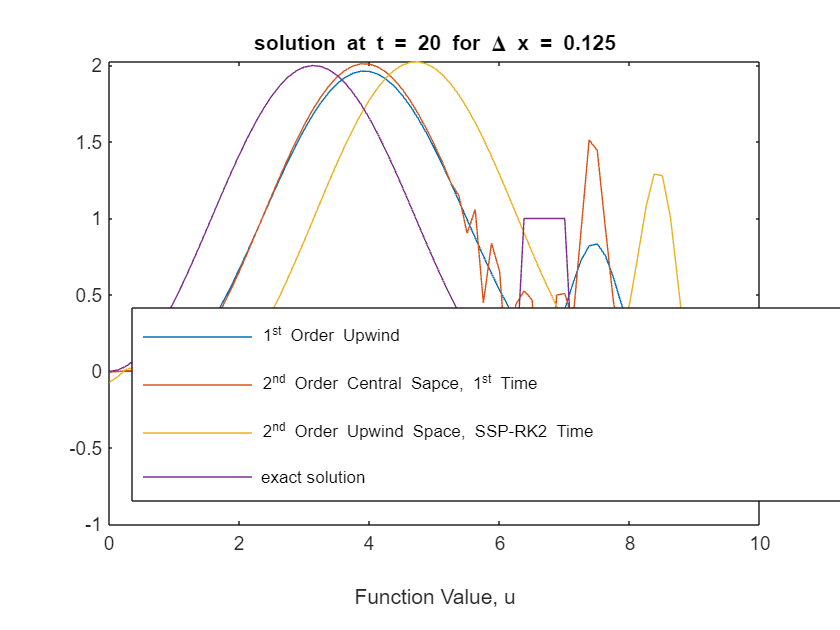

clear; close; clc;
c = 1; % wave speed 

% TODO: get clarification on what the figures wanted should look like

% problem 1 (currently used as the test case)

% initialize  computational parameters
%Delta_x = 10/40; % step size in space
Delta_x_list = [10/40, 10/80]; % step size in space
sigma = .25; % CFL number: sigma = c * Delta_t / Delta_x

for j = 1:2
    Delta_x = Delta_x_list(j)

    Delta_t = sigma / (c*Delta_x); % mesh step size in time

    Xmax = 10;
    Tmax = 50;

    % note the +1 to include x = 0 and t = 0
    spaceSize = Xmax / Delta_x + 1; % we only need 1 period in the domain
    % NOTE: we only need to simulate 1 period (I think)
    timeSize = Tmax / Delta_t + 1; % for now we simulate 10 in time (unsure of temporal period)

    % initialize solution matrix
    u = zeros(spaceSize,timeSize);

    % apply initial copndition
    for i = 1: spaceSize
        u(i,1) = InitialCondition((i-1)*Delta_x); % (i-1)*Delta_x offest of 1 to start at 0 mult by step size Delta_x
    end

    % first order upwind scheme

    u_firstOrder_upwind = u;

    for tStep = 2:timeSize
        u_firstOrder_upwind(1,tStep) = firstOrderUpwind(u_firstOrder_upwind(1,tStep-1), u_firstOrder_upwind(end,tStep-1), sigma); % update the point at the edge (domain is periodic thus wraps around)
        u_firstOrder_upwind(2:end,tStep) = firstOrderUpwind(u_firstOrder_upwind(2:end,tStep-1), u_firstOrder_upwind(1:end-1,tStep-1), sigma); % update all the points not interacting with the edge of the boundary
    end


    % second order central difference

    u_secOrderCentDiff_fisrtTime = u;

    for tStep = 2:timeSize
        u_secOrderCentDiff_fisrtTime(1,tStep) =  secondOrderCentralDifferenceSpace_firstOrderTime(u_secOrderCentDiff_fisrtTime(1,tStep-1), u_secOrderCentDiff_fisrtTime(2,tStep-1), u_secOrderCentDiff_fisrtTime(end,tStep-1), sigma); % left edge of domain
        u_secOrderCentDiff_fisrtTime(2:end-1,tStep) =  secondOrderCentralDifferenceSpace_firstOrderTime(u_secOrderCentDiff_fisrtTime(2:end-1,tStep-1), u_secOrderCentDiff_fisrtTime(3:end,tStep-1), u_secOrderCentDiff_fisrtTime(1:end-2,tStep-1), sigma); % most of domain
        u_secOrderCentDiff_fisrtTime(end,tStep) =  secondOrderCentralDifferenceSpace_firstOrderTime(u_secOrderCentDiff_fisrtTime(end,tStep-1), u_secOrderCentDiff_fisrtTime(1,tStep-1), u_secOrderCentDiff_fisrtTime(end-1,tStep-1), sigma); % right edge of domain
    end


    % Second Order Upwind in space SSP RK2 in time

    u_SOUWSpace_SSPRK2Time = u;
    u_star = zeros(spaceSize,1);

    %TODO: implement with residuals
    for tStep = 2:timeSize % could vecorization be improved by addign a wrap around element at end of array? or maybe asseble it as it is passed as an argument

        % compute the intermediate step
        u_star(1) = SOUWSpace_SSPRK2Time_star(u_SOUWSpace_SSPRK2Time(1,tStep-1), u_SOUWSpace_SSPRK2Time(end,tStep-1), u_SOUWSpace_SSPRK2Time(end-1,tStep-1), sigma); % left most edge of domain
        u_star(2) = SOUWSpace_SSPRK2Time_star(u_SOUWSpace_SSPRK2Time(2,tStep-1), u_SOUWSpace_SSPRK2Time(1,tStep-1), u_SOUWSpace_SSPRK2Time(end,tStep-1), sigma); % next to left edge of domain
        u_star(3:end) = SOUWSpace_SSPRK2Time_star(u_SOUWSpace_SSPRK2Time(3:end,tStep-1), u_SOUWSpace_SSPRK2Time(2:end-1,tStep-1), u_SOUWSpace_SSPRK2Time(1:end-2,tStep-1), sigma); % most of domain

        % compute the next step
        u_SOUWSpace_SSPRK2Time(1,tStep) = SOUWSpace_SSPRK2Time_star(u_star(1), u_star(end), u_star(end-1), sigma); % left most edge of domain
        u_SOUWSpace_SSPRK2Time(2,tStep) = SOUWSpace_SSPRK2Time_star(u_star(2), u_star(1), u_star(end), sigma); % next to left edge of domain
        u_SOUWSpace_SSPRK2Time(3:end,tStep) = SOUWSpace_SSPRK2Time_star(u_star(3:end), u_star(2:end-1), u_star(1:end-2), sigma); % most of domain
    end


    % ploting

    % [X,T] = meshgrid(0:Delta_t:Tmax, 0:Delta_x:Xmax);
    %
    % surf(T, X, u_firstOrder_upwind); title("First Order Upwind"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)")
    %
    % surf(T, X, u_secOrderCentDiff_fisrtTime); title("Second-Order Central-Diff Space First-Order Time"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)")
    %
    % surf(T, X, u_SOUWSpace_SSPRK2Time); title("SO UW Space SSP-RK2 Time"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)")
    %
    % %TODO: label Delta_x of the figures
    %
    % figure;
    % subplot(1,3,1);
    % surf(T, X, u_firstOrder_upwind); title("First Order Upwind"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)");
    % subplot(1,3,2);
    % surf(T, X, u_secOrderCentDiff_fisrtTime); title("Second-Order Central-Diff Space First-Order Time"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)");
    % subplot(1,3,3);
    % surf(T, X, u_SOUWSpace_SSPRK2Time); title("SO UW Space SSP-RK2 Time"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)");
    %
    % figure;
    % t = tiledlayout(1,3);
    % ax1 = nexttile;
    % surf(T, X, u_firstOrder_upwind); title("First Order Upwind"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)");
    % ax2 = nexttile;
    % surf(T, X, u_secOrderCentDiff_fisrtTime); title("Second-Order Central-Diff Space First-Order Time"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)");
    % ax3 = nexttile;
    % surf(T, X, u_SOUWSpace_SSPRK2Time); title("SO UW Space SSP-RK2 Time"); xlabel("Space"), ylabel("Time"); zlabel("u(x,t)");
    % linkaxes([ax1, ax2, ax3]);


    % compute the exact solution
    % soln to the wave equation u_t + c*u_x = 0 is given by u(t) = f(x-c*t)
    % thus it is the intial condition offest by the wavespeed times time.

    t_eval = timeSize; % evaluate the exact solution at the last point we simulate
    t_eval = Delta_t * size(u,1)
    t_eval = 20
    for i = 1: spaceSize
        x = (i-1)*Delta_x; % compute spatial loacation
        x_shifted = mod(x - c*t_eval,Xmax); % periodic boundary condition so take mod domain
        u_20(i) = InitialCondition(x_shifted); % find value of solution at given location
    end


    %for debug
    fprintf("delta x = %g \n",Delta_x)

    % Plots required for assignment
    x = linspace(0,10,length(u_20));

    figure;
    plot(x,u_firstOrder_upwind(:,end)); hold on;
    plot(x,u_secOrderCentDiff_fisrtTime(:,end))
    plot(x,u_SOUWSpace_SSPRK2Time(:,end))
    plot(x,u_20);
    title(sprintf("solution at t = 20 for \\Delta x = %g",Delta_x),Interpreter="tex");
    xlabel("Position, x")
    xlabel("Function Value, u")
    legend(["1^{st} Order Upwind", "2^{nd} Order Central Sapce, 1^{st} Time", "2^{nd} Order Upwind Space, SSP-RK2 Time", "exact solution"], Location="southwest")
    hold off;
    drawnow;

end

function u = InitialCondition(x) % configures the initial condition on the domain
    if(x <= 2*pi)
        u = 1 - cos(x);
    elseif(x <= 7 && x <= 9)
        u = 1;
    else
        u = 0;
    end
end


function u_i_n_plus_1 = firstOrderUpwind(u_i_n, u_i_minus_1_n, sigma)
    u_i_n_plus_1 =  u_i_n  - sigma*(u_i_n - u_i_minus_1_n);
end

function u_i_n_plus_1 = secondOrderCentralDifferenceSpace_firstOrderTime(u_i_n, u_i_n_plus_1, u_i_minus_1_n, sigma)
    u_i_n_plus_1 =  u_i_n  - sigma/2 *(u_i_n_plus_1 - u_i_minus_1_n);
end

%TODO: implement with residuals
function u_i_star = SOUWSpace_SSPRK2Time_star(u_i_n, u_i_minus_1_n, u_i_minus_2_n, sigma)
    u_i_star =  u_i_n  - sigma/2 *(3 *u_i_n - 4 * u_i_minus_1_n + u_i_minus_2_n);
end

%TODO: implement with residuals
function u_i_n_plus_1 = SOUWSpace_SSPRK2Time(u_i_n, u_i_star, u_i_minus_1_star, u_i_minus_2_star, sigma)
    u_i_n_plus_1 = 1/2 * (u_i_n + u_i_star - sigma/2 *(3 *u_i_star - 4 * u_i_minus_1_star + u_i_minus_2_star));
end